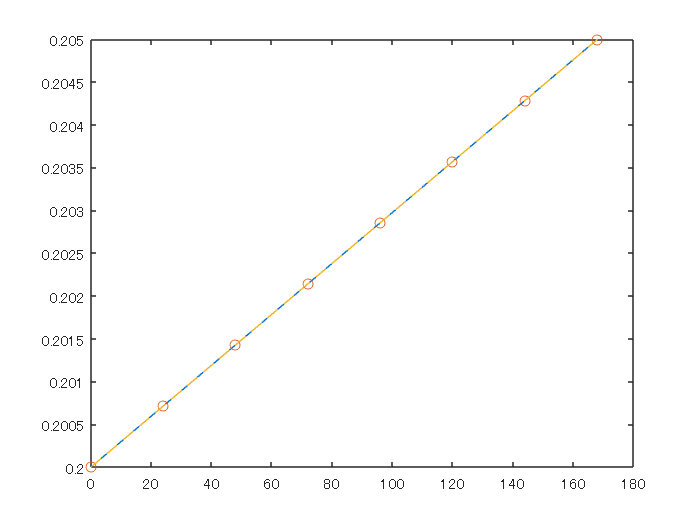

% initial state
V0 = 0.2;       % [L]
Xv0 = 2E+8;     % [cell]
Xt0 = 2E+8;     % [cell]
Glc0 = 25.1;    % [mM]
Gln0 = 5.01;    % [mM]
Lac0 = 0;       % [mM]
Amm0 = 0;       % [mM]
mAb_ext0 = 100; % [mg/L]
x0 = [V0;Xv0;Xt0;Glc0;Gln0;Lac0;Amm0;mAb_ext0];


Y_mAb_X = 3.0583E-12;
mnt_mAb = 1.1989E-08;
Q_in = 0.005/168;
Ts = 24;
N = 7;

ODEFUN = @(t,x) Kontoravdi2010RStateFcn(x,Q_in,Y_mAb_X,mnt_mAb);

tspan = [0, 168];
[TOUT,XOUT] = ode45(ODEFUN,tspan,x0);

% Euler method
Nstep = 168;
XEuler = x0';
xnew = x0;
dt = 168/Nstep;
for i = 1:Nstep
    xnew = xnew + dt*Kontoravdi2010RStateFcn(xnew,Q_in,Y_mAb_X,mnt_mAb);
    XEuler = [XEuler; xnew'];
end


XDT = x0';
xnew = x0;
for day = 1:7
    xnew = Kontoravdi2010RStateFcnDTEuler(xnew,Q_in,24);
    XDT = [XDT; xnew'];
end

% V
plot(TOUT,XOUT(:,1))
hold on
plot(Ts*(0:7)',XDT(:,1),'o')
plot(dt*(0:Nstep)',XEuler(:,1),'--')
hold off

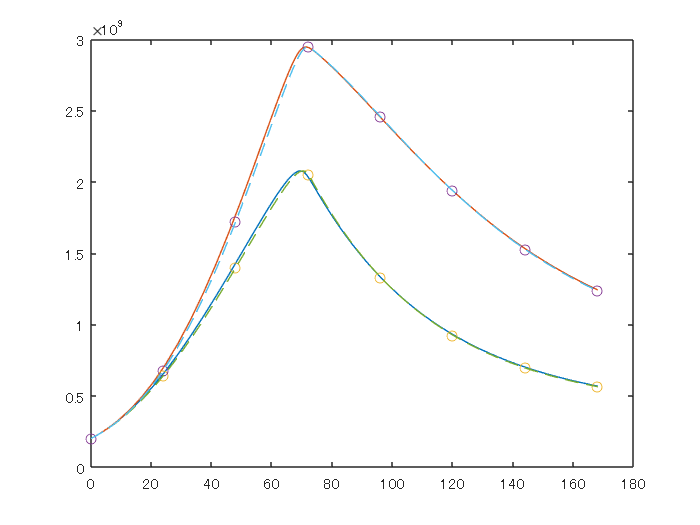

% Xv, Xt
plot(TOUT,XOUT(:,[2 3]))
hold on
plot(Ts*(0:7)',XDT(:,[2 3]),'o')
plot(dt*(0:Nstep)',XEuler(:,[2,3]),'--')
hold off

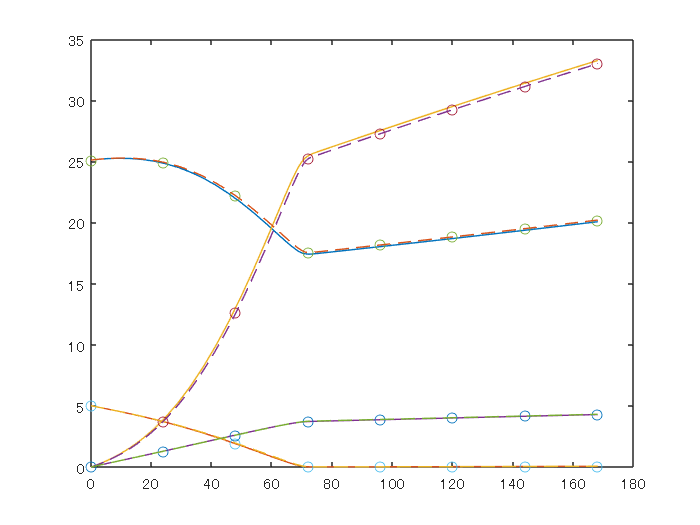

% Glc, Gln, Lac, Amm
plot(TOUT,XOUT(:,4:7))
hold on
plot(Ts*(0:7)',XDT(:,4:7),'o')
plot(dt*(0:Nstep)',XEuler(:,4:7),'--')
hold off

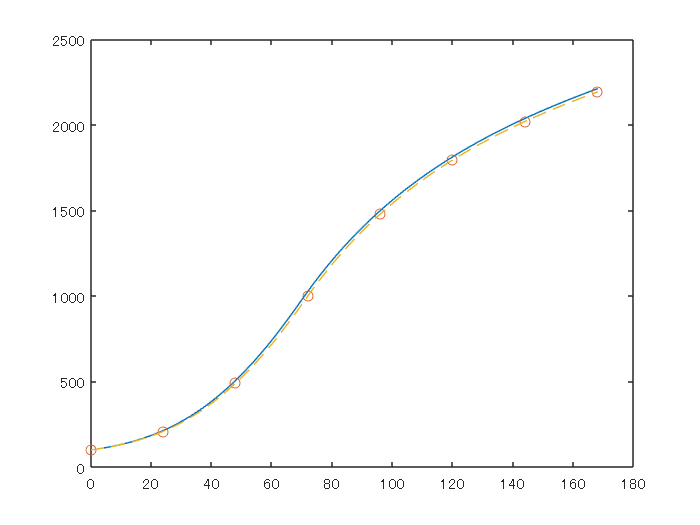

% mAb
plot(TOUT,XOUT(:,8))
hold on
plot(Ts*(0:7)',XDT(:,8),'o')
plot(dt*(0:Nstep)',XEuler(:,8),'--')
hold off